Discussion HW2

A spherical object, e.g. a baseball, is moving in air with an initial speed of 30 m/s and an initial angle of 30 degrees above the horizon. Use a mass m = 0.15 kg, diameter D = 7 cm, and γ = 0.25 N/s`2`m`4`, g = 10 m/s`2`

**1.** Derive and write down the differential equations for the speeds vx(t) and vz (t).


$$\begin{array}{l}
F_{\textrm{Drag}} =-\textrm{cv}\vec{v} =m\frac{d\vec{v} }{\textrm{dt}}\\
\frac{dv_x }{\textrm{dt}}=-\frac{c}{m}v_x \vec{v} 
\end{array}$$



$$\begin{array}{l}
\frac{dv_z }{\textrm{dt}}=-g-\frac{c}{m}v_z \vec{v} \\
\vec{v} =\sqrt{v_x^2 +v_z^2 }
\end{array}$$


**2.** Write down the finite difference versions for the differential equations. Add a sentence saying how you would implement the equations if you were to use a worksheet. (Feel free to use a worksheet, but this is not required, and don’t submit it. You can use the worksheet to check your solutions for later sections.)


$$\begin{array}{l}
\frac{v_x \left(t+\Delta t\right)-v_x \left(t\right)}{\Delta t}=-\frac{c}{m}v_x \left(t\right)\vec{v\left(t\right)} \\
v_x \left(t+\Delta t\right)=v_x \left(t\right)-\Delta t\frac{c}{m}v_x \left(t\right)\vec{v\left(t\right)} 
\end{array}$$



$$\begin{array}{l}
\frac{v_z \left(\Delta t+t\right)-v_z \left(t\right)}{\Delta t}=-g-\frac{c}{m}v_z \left(t\right)\vec{v\left(t\right)} \\
v_z \left(\Delta t+t\right)=v_z \left(t\right)-\Delta t\left(g+\frac{c}{m}v_z \left(t\right)\vec{v\left(t\right)} \right)
\end{array}$$


To use these equations you would have to start with an initial velocity and time step as well as an angle or a initial velocity component so you can find the initial velocities of both components. Then you would have to fill out the at the same time to have the right numbers to calculate the next step.

**3.** Write a MATLAB livescript to solve the speeds vx(t) and vz (t). Use enough time to make the physics clear. The new element here, compared to what has been done in the discussion (and should be posted soon), is that we are solving for two speeds, not one. So the function we use in ODE45 needs to calculate and output two values not one. Consult the additional help below with this issue.

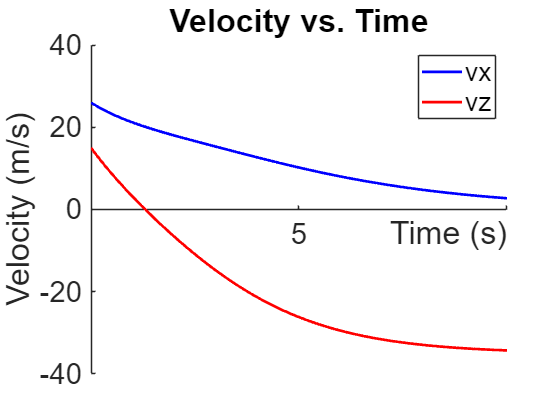

clc; clear all; close all;
% initial velocity variables
v0 = 30;
theta = 30;
function dvdt = odefun(t, v)
% variables
gamma = 0.25;
D = 0.07;
c = gamma*D^2;
m = 0.15;
g = 10;
% initialize empty array
dvdt = zeros(2, 1);
% set dvxdt as first element
dvdt(1) = -(c/m)*v(1)*sqrt(v(1)^2+v(2)^2);
% set dvzdt as second element
dvdt(2) = -g -(c/m)*v(2)*sqrt(v(1)^2+v(2)^2);
end
[t, v] = ode45(@odefun, linspace(0, 10, 100), [v0*cosd(theta), v0*sind(theta)]); % v should be an array with the first column as vx and the second as vz
% plots
hold on
plot(t, v(:, 1), 'Color', 'blue', 'LineWidth', 2)
plot(t, v(:, 2), 'Color', 'red', 'LineWidth', 2)
hold off
% plot settings
ylim([-40, 40])
legend('vx', 'vz')
ax = gca; % code form (https://www.mathworks.com/matlabcentral/answers/20318-drawing-the-x-axis-at-y-0), Kyle Johnson
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
title('Velocity vs. Time')
xlabel('Time (s)', 'Position', [10, -10])
ylabel('Velocity (m/s)')
set(gca, 'fontsize', 22)

clf

**4.** Now pause and think: how would you check whether the solution is correct? After all, this problem has no analytic solution. One way to check your solution is to compare it to a **solution without drag**.

**5. **Add to your livescript code that calculates the speeds in x and z in the absence of drag

and overlay these results in the plots you have generated earlier.


$$\begin{array}{l}
F=-\mathrm{mg}\\
\frac{dv_x }{\mathrm{dt}}=0\\
\frac{{\mathrm{dv}}_y }{\mathrm{dt}}=-g\\
v_x =v_{x,0} \\
v_y =v_{y,0} -\mathrm{gt}
\end{array}$$


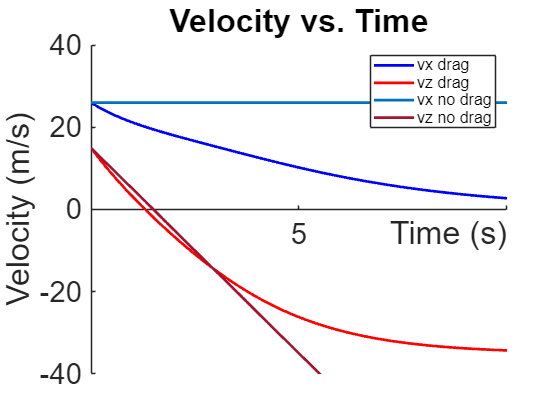

clc;
% initial variables
g=10;
tspan = linspace(0, 10, 100);
v0 = [30*cosd(30), 30*sind(30)];
% velocity calculations without drag
vx = v0(1)+(0)*tspan;
vy = v0(2)-g.*tspan;
%plots
hold on
plot(t, v(:, 1), 'Color', 'blue', 'LineWidth', 2)
plot(t, v(:, 2), 'Color', 'red', 'LineWidth', 2)
plot(tspan, vx, color=[0 0.4470 0.7410], LineWidth=2);
plot(tspan, vy,  color=[0.6350 0.0780 0.1840], LineWidth=2)
hold off
% plot settings
ylim([-40, 40])
hold off
legend('vx drag', 'vz drag', 'vx no drag', 'vz no drag', 'FontSize', 12)
ax = gca; % code form (https://www.mathworks.com/matlabcentral/answers/20318-drawing-the-x-axis-at-y-0), Kyle Johnson
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
title('Velocity vs. Time')
xlabel('Time (s)', 'Position', [10, -10])
ylabel('Velocity (m/s)')
set(gca, 'fontsize', 22)

**6.** Do the results make sense? Interpret the physics in words in the following way:

(1) For each of vx and vz , make at least two word observations comparing the with-drag

to the no-drag solution, and

For vx, we can see the two different lines start at the same point. 

For vz we can see they start at the same point as well as hit 0 at very similar times with the drag solution reaching 0 faster which makes sense as drag would cause the object to decellerate faster.

(2) look at the with-drag motion in vx and vz (by comparing the plots visually) and

make at least one observation about the motion.

The acceration is decreasing, this makes sense because the drag depends on the speed so lower speeds should yield lower drag.

**7**. Are you now confident that your code produces the right results?

Semi-confident, it looks good but more tests will have to be run to determine if the behavior of the line is correct not just it's intercepts.